# Energy Consumption Prediction Model

To predict energy consumption for heating/cooling, we have generated data for houses using different "bands" of setpoints.  Each band follows the adaptive control model but is shifted up or down.  We have 5 bands: upper, upper middle, middle, lower middle, and lower.  For each band we have generated annual data for just heating, just cooling, and with heating and cooling.  We also generated data with constant setpoints for 12C and 32C with just heating, just cooling, and both (these are the setpoints when there are no occupants).  In total we have 6*3=18 sets of data that will be available to train our algorithms.  There will be an algorithm to predict energy consumption when heating and one to predict energy consumption when cooling.  These algorithms will be independent of each other for now.

This code will use the following:

Inputs: 

- Heating: Outdoor Temperature, Indoor Temperature, Heating Setpoint

- Cooling: Outdoor Temperature, Indoor Temperature, Cooling Setpoint

Outputs:

- Heating and Cooling: Energy Consumption (3hrs ahead)

Parameters:

- 6 hours before on the same day

- same hour (-24hrs from current time), 1 hour ahead (-23hrs), 2 hours ahead (-22hrs) for 1 day before

- same hour (-48hrs), 1 hour ahead (-47hrs), 2 hours ahead (-46hrs) for 2 days before

- same hour (-72hrs), 1 hour ahead (-71hrs), 2 hours ahead (-70hrs) for 3 days before

Training and Testing:

- de

% First need to import all the data... I compiled the data into one
% spreadsheet manually but would eventually like to automate this process..
% perhaps in python?
% 
% I saved two workspaces.. I made the first workspace by importing the data
% as column vectors except for the time which is one year with one hour
% timesteps (this is the "separated" workspace).. then in another script I
% appended all the data into arrays sorted by the values (this is the
% "combined" workspace
% 
% The order of the values in the vectors and the columns"matrix" are upper,
% upper mid, mid, lower mid, lower, noOcc (12/32)
%
% Naming convention: {band}_{Heater(H)/AC(A)/Both(HA)}_{value} where HS/CS
% is heating/cooling setpoint and heat/coolEnergy is energy consumption
% when heating/cooling. For the combined workspace the variables are named
% just by the value... the {value}_matrix just has each dataset in a column
% rather than appended onto eachother.
%
% All temperatures are in degrees C and energy consumptions are in kW

% Constants
numInputs = 4; % indoorTemp, outdoorTemp, setpoint
numOutputs = 3; % 3 hours worth of energy consumption
hoursAhead = 3;
parameters = numInputs * (6 + 3*3);

startValues = 101:157100;
trainingSize = 125600;
testSize = 31400;

% Training to get P matrix
u1_heat = ones(trainingSize,numOutputs);
u1_cool = ones(trainingSize,numOutputs);
y1_heat = ones(trainingSize,parameters);
y1_cool = ones(trainingSize,parameters);

for i = 1:trainingSize
    ii = startValues(i);
    % adding values into y1 matrices:
    % same day going 6 hrs before
    y1_heat(i,1) = indoorTemp(ii-1);
    y1_heat(i,2) = indoorTemp(ii-2);
    y1_heat(i,3) = indoorTemp(ii-3);
    y1_heat(i,4) = indoorTemp(ii-4);
    y1_heat(i,5) = indoorTemp(ii-5);
    y1_heat(i,6) = indoorTemp(ii-6);
    y1_heat(i,7) = outdoorTemp(ii-1);
    y1_heat(i,8) = outdoorTemp(ii-2);
    y1_heat(i,9) = outdoorTemp(ii-3);
    y1_heat(i,10) = outdoorTemp(ii-4);
    y1_heat(i,11) = outdoorTemp(ii-5);
    y1_heat(i,12) = outdoorTemp(ii-6);
    y1_heat(i,13) = heatingSetpoint(ii-1);
    y1_heat(i,14) = heatingSetpoint(ii-2);
    y1_heat(i,15) = heatingSetpoint(ii-3);
    y1_heat(i,16) = heatingSetpoint(ii-4);
    y1_heat(i,17) = heatingSetpoint(ii-5);
    y1_heat(i,18) = heatingSetpoint(ii-6);
    
    y1_cool(i,1) = indoorTemp(ii-1);
    y1_cool(i,2) = indoorTemp(ii-2);
    y1_cool(i,3) = indoorTemp(ii-3);
    y1_cool(i,4) = indoorTemp(ii-4);
    y1_cool(i,5) = indoorTemp(ii-5);
    y1_cool(i,6) = indoorTemp(ii-6);
    y1_cool(i,7) = outdoorTemp(ii-1);
    y1_cool(i,8) = outdoorTemp(ii-2);
    y1_cool(i,9) = outdoorTemp(ii-3);
    y1_cool(i,10) = outdoorTemp(ii-4);
    y1_cool(i,11) = outdoorTemp(ii-5);
    y1_cool(i,12) = outdoorTemp(ii-6);
    y1_cool(i,13) = coolingSetpoint(ii-1);
    y1_cool(i,14) = coolingSetpoint(ii-2);
    y1_cool(i,15) = coolingSetpoint(ii-3);
    y1_cool(i,16) = coolingSetpoint(ii-4);
    y1_cool(i,17) = coolingSetpoint(ii-5);
    y1_cool(i,18) = coolingSetpoint(ii-6);
    
    % adding energy consumption
    y1_heat(i,19) = heatingEnergy(ii-1);
    y1_heat(i,20) = heatingEnergy(ii-2);
    y1_heat(i,21) = heatingEnergy(ii-3);
    y1_heat(i,22) = heatingEnergy(ii-4);
    y1_heat(i,23) = heatingEnergy(ii-5);
    y1_heat(i,24) = heatingEnergy(ii-6);
    
    y1_cool(i,19) = coolingEnergy(ii-1);
    y1_cool(i,20) = coolingEnergy(ii-2);
    y1_cool(i,21) = coolingEnergy(ii-3);
    y1_cool(i,22) = coolingEnergy(ii-4);
    y1_cool(i,23) = coolingEnergy(ii-5);
    y1_cool(i,24) = coolingEnergy(ii-6);
    
    % same hour to n hours back for 3 days
    indexCtr = 25;
    for j = 1:hoursAhead
        y1_heat(i,indexCtr) = indoorTemp(ii-24+j-1);
        y1_heat(i,indexCtr+1) = indoorTemp(ii-48+j-1);
        y1_heat(i,indexCtr+2) = indoorTemp(ii-72+j-1);
        y1_heat(i,indexCtr+3) = outdoorTemp(ii-24+j-1);
        y1_heat(i,indexCtr+4) = outdoorTemp(ii-48+j-1);
        y1_heat(i,indexCtr+5) = outdoorTemp(ii-72+j-1);
        y1_heat(i,indexCtr+6) = heatingSetpoint(ii-24+j-1);
        y1_heat(i,indexCtr+7) = heatingSetpoint(ii-48+j-1);
        y1_heat(i,indexCtr+8) = heatingSetpoint(ii-72+j-1);
        y1_heat(i,indexCtr+9) = heatingEnergy(ii-24+j-1);
        y1_heat(i,indexCtr+10) = heatingEnergy(ii-48+j-1);
        y1_heat(i,indexCtr+11) = heatingEnergy(ii-72+j-1);
        
        y1_cool(i,indexCtr) = indoorTemp(ii-24+j-1);
        y1_cool(i,indexCtr+1) = indoorTemp(ii-48+j-1);
        y1_cool(i,indexCtr+2) = indoorTemp(ii-72+j-1);
        y1_cool(i,indexCtr+3) = outdoorTemp(ii-24+j-1);
        y1_cool(i,indexCtr+4) = outdoorTemp(ii-48+j-1);
        y1_cool(i,indexCtr+5) = outdoorTemp(ii-72+j-1);
        y1_cool(i,indexCtr+6) = coolingSetpoint(ii-24+j-1);
        y1_cool(i,indexCtr+7) = coolingSetpoint(ii-48+j-1);
        y1_cool(i,indexCtr+8) = coolingSetpoint(ii-72+j-1);
        y1_cool(i,indexCtr+9) = coolingEnergy(ii-24+j-1);
        y1_cool(i,indexCtr+10) = coolingEnergy(ii-48+j-1);
        y1_cool(i,indexCtr+11) = coolingEnergy(ii-72+j-1);
        
        indexCtr = indexCtr+12;
    end
    
    % making u1 matrices:
    u1_heat(i,1) = heatingEnergy(ii);
    u1_heat(i,2) = heatingEnergy(ii+1);
    u1_heat(i,3) = heatingEnergy(ii+2);
    
    u1_cool(i,1) = coolingEnergy(ii);
    u1_cool(i,2) = coolingEnergy(ii+1);
    u1_cool(i,3) = coolingEnergy(ii+2);
end

% Solving for P Matrices:
p_heat = (y1_heat'*y1_heat)^-1*y1_heat'*u1_heat;
p_cool = (y1_cool'*y1_cool)^-1*y1_cool'*u1_cool;

% Testing
actual_heat = ones(testSize,numOutputs);
actual_cool = ones(testSize,numOutputs);
y2_heat = ones(testSize,parameters);
y2_cool = ones(testSize,parameters);

for i = 1:testSize
    ii = startValues(i);
    % adding values into y2 matrices:
    % same day going 6 hrs before
    y2_heat(i,1) = indoorTemp(ii-1);
    y2_heat(i,2) = indoorTemp(ii-2);
    y2_heat(i,3) = indoorTemp(ii-3);
    y2_heat(i,4) = indoorTemp(ii-4);
    y2_heat(i,5) = indoorTemp(ii-5);
    y2_heat(i,6) = indoorTemp(ii-6);
    y2_heat(i,7) = outdoorTemp(ii-1);
    y2_heat(i,8) = outdoorTemp(ii-2);
    y2_heat(i,9) = outdoorTemp(ii-3);
    y2_heat(i,10) = outdoorTemp(ii-4);
    y2_heat(i,11) = outdoorTemp(ii-5);
    y2_heat(i,12) = outdoorTemp(ii-6);
    y2_heat(i,13) = heatingSetpoint(ii-1);
    y2_heat(i,14) = heatingSetpoint(ii-2);
    y2_heat(i,15) = heatingSetpoint(ii-3);
    y2_heat(i,16) = heatingSetpoint(ii-4);
    y2_heat(i,17) = heatingSetpoint(ii-5);
    y2_heat(i,18) = heatingSetpoint(ii-6);
    
    y2_cool(i,1) = indoorTemp(ii-1);
    y2_cool(i,2) = indoorTemp(ii-2);
    y2_cool(i,3) = indoorTemp(ii-3);
    y2_cool(i,4) = indoorTemp(ii-4);
    y2_cool(i,5) = indoorTemp(ii-5);
    y2_cool(i,6) = indoorTemp(ii-6);
    y2_cool(i,7) = outdoorTemp(ii-1);
    y2_cool(i,8) = outdoorTemp(ii-2);
    y2_cool(i,9) = outdoorTemp(ii-3);
    y2_cool(i,10) = outdoorTemp(ii-4);
    y2_cool(i,11) = outdoorTemp(ii-5);
    y2_cool(i,12) = outdoorTemp(ii-6);
    y2_cool(i,13) = coolingSetpoint(ii-1);
    y2_cool(i,14) = coolingSetpoint(ii-2);
    y2_cool(i,15) = coolingSetpoint(ii-3);
    y2_cool(i,16) = coolingSetpoint(ii-4);
    y2_cool(i,17) = coolingSetpoint(ii-5);
    y2_cool(i,18) = coolingSetpoint(ii-6);
    
    % adding energy consumption
    y2_heat(i,19) = heatingEnergy(ii-1);
    y2_heat(i,20) = heatingEnergy(ii-2);
    y2_heat(i,21) = heatingEnergy(ii-3);
    y2_heat(i,22) = heatingEnergy(ii-4);
    y2_heat(i,23) = heatingEnergy(ii-5);
    y2_heat(i,24) = heatingEnergy(ii-6);
   
    y2_cool(i,19) = coolingEnergy(ii-1);
    y2_cool(i,20) = coolingEnergy(ii-2);
    y2_cool(i,21) = coolingEnergy(ii-3);
    y2_cool(i,22) = coolingEnergy(ii-4);
    y2_cool(i,23) = coolingEnergy(ii-5);
    y2_cool(i,24) = coolingEnergy(ii-6);
    
    % same hour to n hours back for 3 days
    indexCtr = 25;
    for j = 1:hoursAhead
        y2_heat(i,indexCtr) = indoorTemp(ii-24+j-1);
        y2_heat(i,indexCtr+1) = indoorTemp(ii-48+j-1);
        y2_heat(i,indexCtr+2) = indoorTemp(ii-72+j-1);
        y2_heat(i,indexCtr+3) = outdoorTemp(ii-24+j-1);
        y2_heat(i,indexCtr+4) = outdoorTemp(ii-48+j-1);
        y2_heat(i,indexCtr+5) = outdoorTemp(ii-72+j-1);
        y2_heat(i,indexCtr+6) = heatingSetpoint(ii-24+j-1);
        y2_heat(i,indexCtr+7) = heatingSetpoint(ii-48+j-1);
        y2_heat(i,indexCtr+8) = heatingSetpoint(ii-72+j-1);
        y2_heat(i,indexCtr+9) = heatingEnergy(ii-24+j-1);
        y2_heat(i,indexCtr+10) = heatingEnergy(ii-48+j-1);
        y2_heat(i,indexCtr+11) = heatingEnergy(ii-72+j-1);
        
        y2_cool(i,indexCtr) = indoorTemp(ii-24+j-1);
        y2_cool(i,indexCtr+1) = indoorTemp(ii-48+j-1);
        y2_cool(i,indexCtr+2) = indoorTemp(ii-72+j-1);
        y2_cool(i,indexCtr+3) = outdoorTemp(ii-24+j-1);
        y2_cool(i,indexCtr+4) = outdoorTemp(ii-48+j-1);
        y2_cool(i,indexCtr+5) = outdoorTemp(ii-72+j-1);
        y2_cool(i,indexCtr+6) = coolingSetpoint(ii-24+j-1);
        y2_cool(i,indexCtr+7) = coolingSetpoint(ii-48+j-1);
        y2_cool(i,indexCtr+8) = coolingSetpoint(ii-72+j-1);
        y2_cool(i,indexCtr+9) = coolingEnergy(ii-24+j-1);
        y2_cool(i,indexCtr+10) = coolingEnergy(ii-48+j-1);
        y2_cool(i,indexCtr+11) = coolingEnergy(ii-72+j-1);
        
        indexCtr = indexCtr+12;
    end
    
    % actual values:
    actual_heat(i,1) = heatingEnergy(ii);
    actual_heat(i,2) = heatingEnergy(ii+1);
    actual_heat(i,3) = heatingEnergy(ii+2);
    
    actual_cool(i,1) = coolingEnergy(ii);
    actual_cool(i,2) = coolingEnergy(ii+1);
    actual_cool(i,3) = coolingEnergy(ii+2);
end

% solving for u2 matrices:
u2_heat = y2_heat*p_heat;
u2_cool = y2_cool*p_cool;



Now I am going to process the data and see how good the prediction is compared to the actual value.  I will show a visual representation and a table of values.

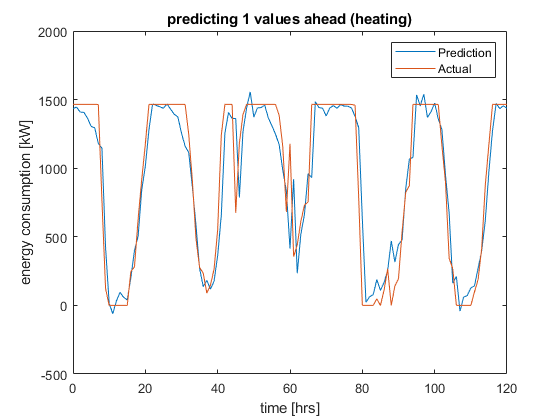

aveError_heat = zeros(1,hoursAhead);
std_heat = zeros(1,hoursAhead);
for k = 1:hoursAhead
    error = abs(actual_heat(:,k)-u2_heat(:,k));   % CHANGE THIS LINE TO LOOK AT DIFFERENT VALUES
    aveError_heat(k) = sum(error)/length(error);
    mu = aveError_heat(k)*ones(testSize,1);
    var = sum((error-mu).^2)/length(error);
    std_heat(k) = sqrt(var);
end

timeVar = [0:(testSize-1)]';    % used to plot results

figure(1)
plot(timeVar,u2_heat(:,1),timeVar,actual_heat(:,1))
title('predicting 1 values ahead (heating)')
xlabel('time [hrs]')
ylabel('energy consumption [kW]')
legend('Prediction', 'Actual')
axis([00 24*5 -500 2000])

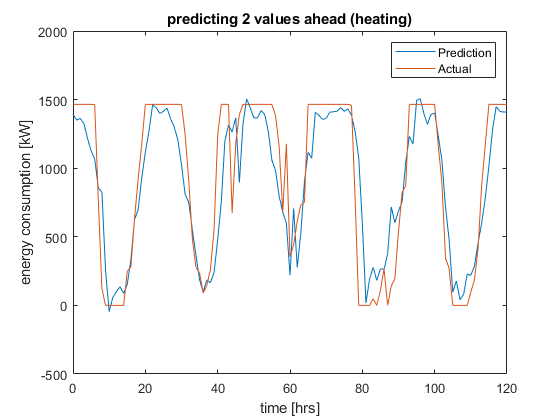


figure(2)
plot(timeVar,u2_heat(:,2),timeVar,actual_heat(:,2))
title('predicting 2 values ahead (heating)')
xlabel('time [hrs]')
ylabel('energy consumption [kW]')
legend('Prediction', 'Actual')
axis([00 24*5 -500 2000])

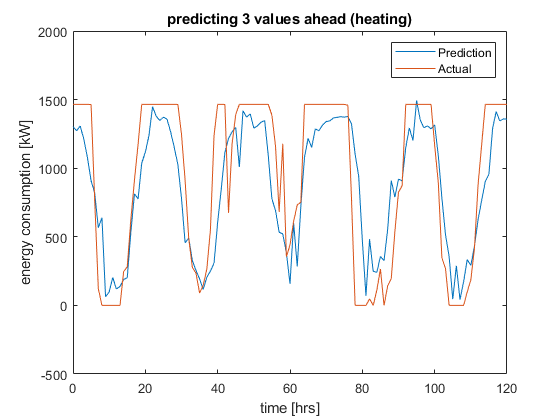


figure(3)
plot(timeVar,u2_heat(:,3),timeVar,actual_heat(:,3))
title('predicting 3 values ahead (heating)')
xlabel('time [hrs]')
ylabel('energy consumption [kW]')
legend('Prediction', 'Actual')
axis([00 24*5 -500 2000])

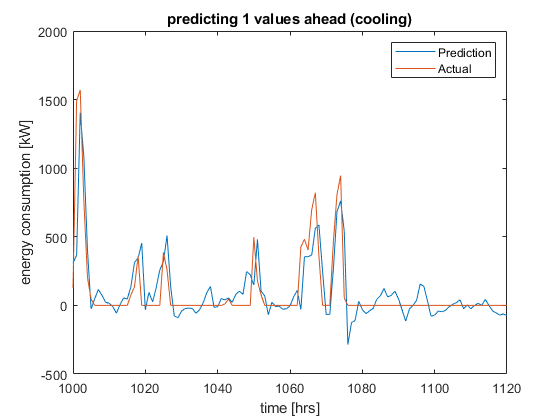


% Now for cooling...

aveError_cool = zeros(1,hoursAhead);
std_cool = zeros(1,hoursAhead);
for k = 1:hoursAhead
    error = abs(actual_cool(:,k)-u2_cool(:,k));   % CHANGE THIS LINE TO LOOK AT DIFFERENT VALUES
    aveError_cool(k) = sum(error)/length(error);
    mu = aveError_cool(k)*ones(testSize,1);
    var = sum((error-mu).^2)/length(error);
    std_cool(k) = sqrt(var);
end

timeVar = [0:(testSize-1)]';    % used to plot results

figure(4)
plot(timeVar,u2_cool(:,1),timeVar,actual_cool(:,1))
title('predicting 1 values ahead (cooling)')
xlabel('time [hrs]')
ylabel('energy consumption [kW]')
legend('Prediction', 'Actual')
axis([1000 1000+24*5 -500 2000])

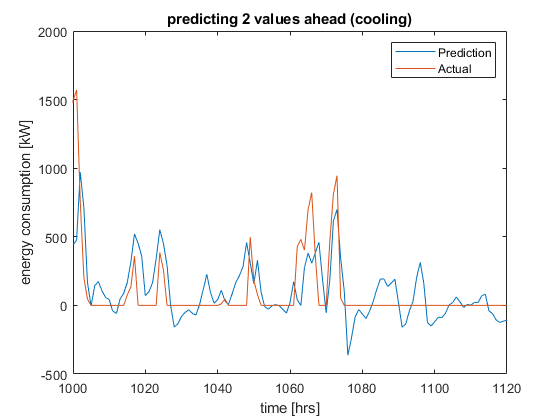


figure(5)
plot(timeVar,u2_cool(:,2),timeVar,actual_cool(:,2))
title('predicting 2 values ahead (cooling)')
xlabel('time [hrs]')
ylabel('energy consumption [kW]')
legend('Prediction', 'Actual')
axis([1000 1000+24*5 -500 2000])

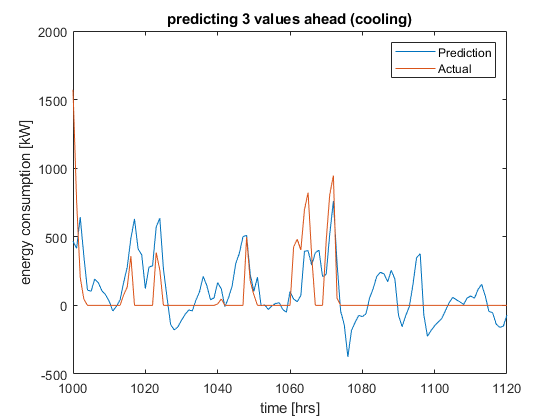


figure(6)
plot(timeVar,u2_cool(:,3),timeVar,actual_cool(:,3))
title('predicting 3 values ahead (cooling)')
xlabel('time [hrs]')
ylabel('energy consumption [kW]')
legend('Prediction', 'Actual')
axis([1000 1000+24*5 -500 2000])